# Análise dos dados dos experimentos e obtenção dos modelos

clear
size_image = [0, 0, 600, 400];

#### Constantes conhecidas

g = 9.81;      % gravidade
G_r = 4.4;     % relação da caixa de redução

#### Constantes medidas

V_max = 11.0;  % V  - multimetro na saída da ponte H
L_1 = 7.5/100; % m  - régua
L_2 = 13/100;  % m  - régua
m_1 = 40/1000; % kg - balança
m_2 = 27/1000; % kg - balança

#### Configurações do experimento

T = 60;
f0 = 0.1;
f1 = 10;

#### Configurações do Matlab 

type = 'P1';
init_sys = idproc(type);
opt = procestOptions;              
opt.InitialCondition = 'zero';     
opt.Display = 'off';     

## Experimento 1 - Pêndulo fixo em 180°

exp_1 = readtable("exp_2.csv");

exp_1.t = exp_1.t;
exp_1.u = exp_1.u;
exp_1.V = exp_1.u * V_max;
exp_1.theta_1 = exp_1.theta_1;
exp_1

exp_1 = 5998×4 table
       t          u       theta_1       V   
    _______    _______    _______    _______

      4e-05      1e-05       0       0.00011
    0.02005     0.0063       0        0.0693
    0.04007    0.01259       0       0.13849
    0.06007    0.01888       0       0.20768
    0.08008    0.02516       0       0.27676
    0.10009    0.03145       0       0.34595
    0.12009    0.03773       0       0.41503
    0.14011    0.04401       0       0.48411
    0.16011    0.05028       0       0.55308
    0.18013    0.05655       0       0.62205
    0.20016    0.06282       0       0.69102
    0.22016    0.06907       0       0.75977
    0.24017    0.07531       0       0.82841
    0.26017    0.08154       0       0.89694
    0.28019    0.08777       0       0.96547
    0.30021    0.09398       0        1.0338


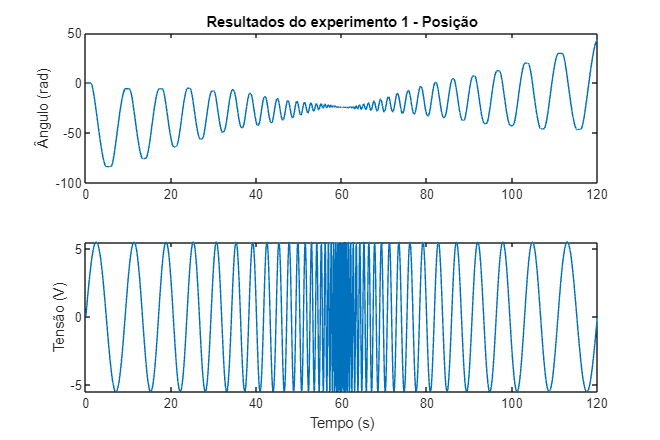

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.theta_1)
xlim([0 T*2])
title("Resultados do experimento 1 - Posição"), ylabel("Ângulo (rad)")

subplot(2,1,2)
plot(exp_1.t, exp_1.V)
xlim([0 T*2]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

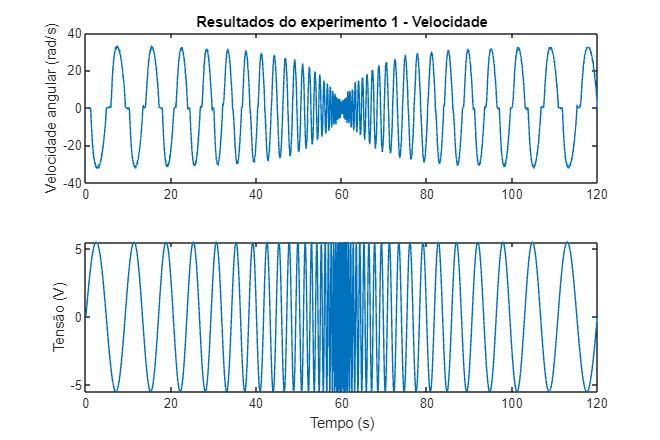

exp_1.omega_1 = gradient(exp_1.theta_1, exp_1.t);

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.omega_1)
xlim([0 T*2])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_1.t, exp_1.V)
xlim([0 T*2]), xlabel("Tempo (s)"), ylabel("Tensão (V)")
saveas(gcf, "result_exp1.png")

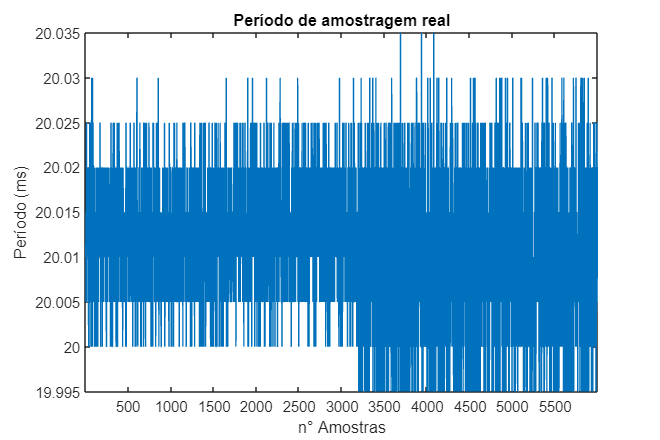

figure("Position", size_image)
plot(1e3*gradient(exp_1.t))
title("Período de amostragem real"), ylabel("Período (ms)"), xlabel("n° Amostras")
axis tight

Ts = mean(gradient(exp_1.t))

Ts = 0.0200

K1 = max(exp_1.omega_1)./max(exp_1.V) % ganho da planta

K1 = 6.0453

#### Estimativa do modelo a partir do ganho inicial K1

data_exp_1 = iddata(exp_1.omega_1, exp_1.V, Ts);
init_sys.Structure.Kp.Value = K1;

G_dtheta_1_exp1 = procest(data_exp_1, init_sys, opt);
G_dtheta_1_exp1 = tf(G_dtheta_1_exp1)

G_dtheta_1_exp1 =
 
  From input "u1" to output "y1":
    -5.797
  -----------
  0.326 s + 1
 
Continuous-time transfer function.
Model Properties


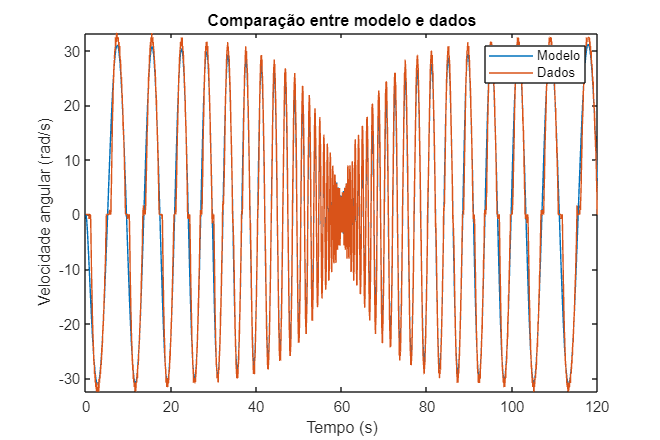

t_homogen = (0:length(exp_1.t)-1) * Ts;
y = lsim(G_dtheta_1_exp1, exp_1.V, t_homogen);

figure("Position", size_image)
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_1.t, exp_1.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação entre modelo e dados"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight

## Experimento 2 - Motor sem haste do pêndulo

exp_2 = readtable("exp_1.csv");

exp_2.t = exp_2.t;
exp_2.u = exp_2.u;
exp_2.V = exp_2.u * V_max;
exp_2.theta_1 = exp_2.theta_1;
exp_2

exp_2 = 5998×4 table
       t          u       theta_1       V   
    _______    _______    _______    _______

      4e-05      1e-05       0       0.00011
    0.02006     0.0063       0        0.0693
    0.04007    0.01259       0       0.13849
    0.06007    0.01888       0       0.20768
    0.08008    0.02516       0       0.27676
    0.10009    0.03145       0       0.34595
    0.12009    0.03773       0       0.41503
    0.14011    0.04401       0       0.48411
    0.16011    0.05028       0       0.55308
    0.18013    0.05655       0       0.62205
    0.20013    0.06281       0       0.69091
    0.22015    0.06907       0       0.75977
    0.24018    0.07531       0       0.82841
     0.2602    0.08155       0       0.89705
    0.28021    0.08778       0       0.96558
    0.30023    0.09399       0        1.0339


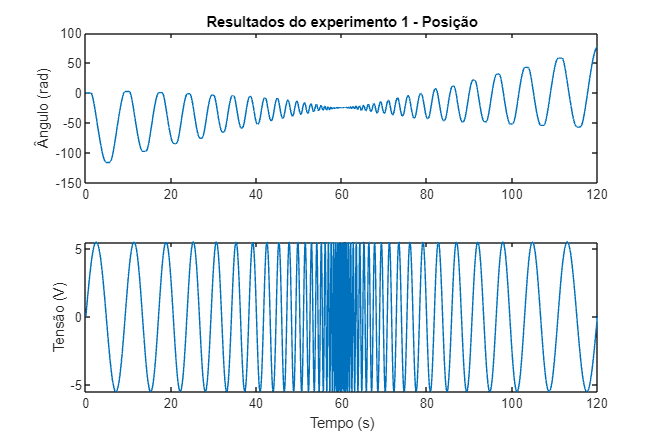

figure("Position", size_image)
subplot(2,1,1)
plot(exp_2.t, exp_2.theta_1)
xlim([0 T*2])
title("Resultados do experimento 1 - Posição"), ylabel("Ângulo (rad)")

subplot(2,1,2)
plot(exp_2.t, exp_2.V)
xlim([0 T*2]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

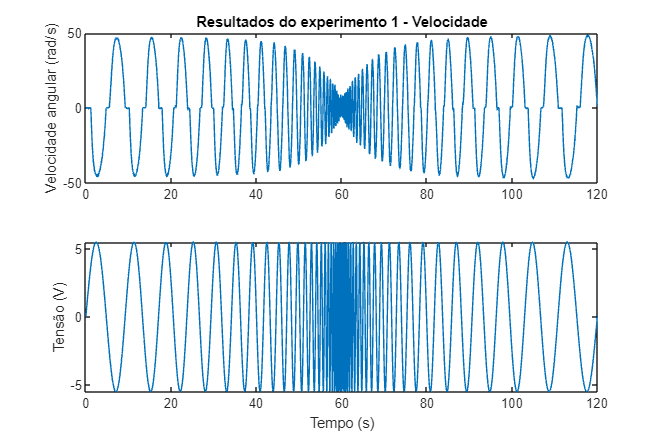

exp_2.omega_1 = gradient(exp_2.theta_1, exp_2.t);

figure("Position", size_image)
subplot(2,1,1)
plot(exp_2.t, exp_2.omega_1)
xlim([0 T*2])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_2.t, exp_2.V)
xlim([0 T*2]), xlabel("Tempo (s)"), ylabel("Tensão (V)")

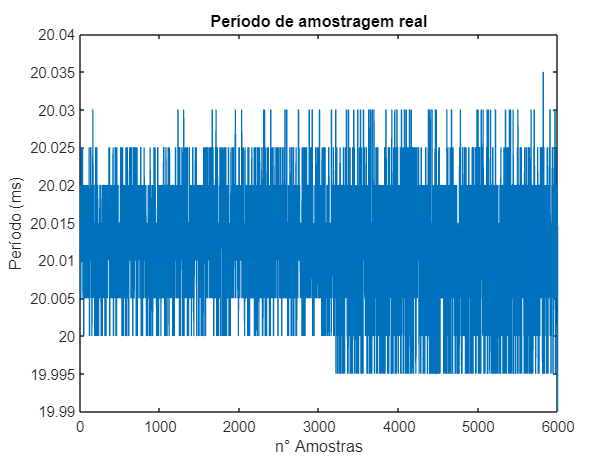

figure
plot(1e3*gradient(exp_2.t))
title("Período de amostragem real"), ylabel("Período (ms)"), xlabel("n° Amostras")

Ts = mean(gradient(exp_2.t))

Ts = 0.0200

s = tf('s');
K2 = max(exp_2.omega_1)./max(exp_2.V) % ganho da planta

K2 = 8.8534

tau2 = 0.24; % constante de tempo da planta - parâmetro ajustado manualmente com base no gráfico abaixo
G_dtheta_1_exp2 = K2/(tau2*s + 1)

G_dtheta_1_exp2 =
 
    8.853
  ----------
  0.24 s + 1
 
Continuous-time transfer function.
Model Properties


t_homogen = (0:length(exp_2.t)-1) * Ts

t_homogen =          0    0.0200    0.0400    0.0600    0.0800    0.1001    0.1201    0.1401    0.1601    0.1801    0.2001    0.2201    0.2401    0.2601    0.2802    0.3002    0.3202    0.3402    0.3602    0.3802    0.4002    0.4202    0.4403    0.4603    0.4803    0.5003    0.5203    0.5403    0.5603    0.5803    0.6003    0.6204    0.6404    0.6604    0.6804    0.7004    0.7204    0.7404    0.7604    0.7804    0.8005    0.8205    0.8405    0.8605    0.8805    0.9005    0.9205    0.9405    0.9606    0.9806


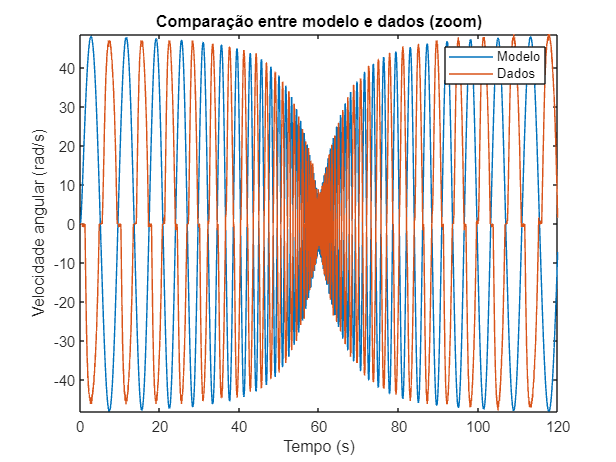

y = lsim(G_dtheta_1_exp2, exp_2.V, t_homogen);
figure
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_2.t, exp_2.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação entre modelo e dados (zoom)"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight
xlim([0 T*2])

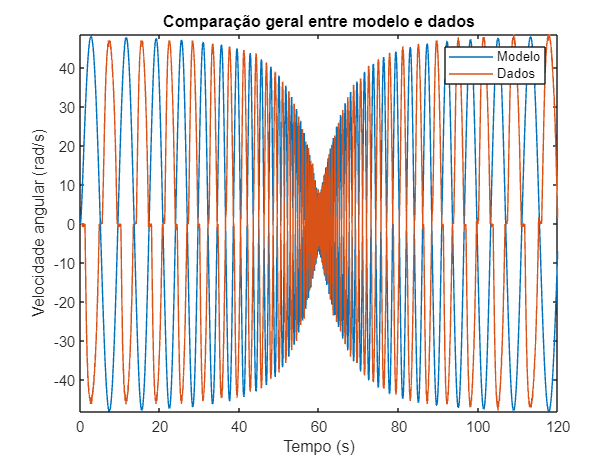

figure
plot(t_homogen, y, "LineWidth", 0.1)
hold on
plot(exp_2.t, exp_2.omega_1, "LineWidth", 0.1)
legend("Modelo", "Dados"), title("Comparação geral entre modelo e dados"), xlabel("Tempo (s)"), ylabel("Velocidade angular (rad/s)")
axis tight

## Heurística

% G_J1 = zpk(G_J1), G_J0 = zpk(G_J0)
% K_J1 = -G_J1.K/G_J1.P{1}, tau_J1 = -1/G_J1.P{1}
% G_J1n = tf(K_J1, [tau_J1 1])
% K_J0 = -G_J0.K/G_J0.P{1}, tau_J0 = -1/G_J0.P{1}
% G_J0n = tf(K_J1, [tau_J0 1])
% figure
% step(G_J1, [0 4])
% hold on
% step(G_J0, [0 4])
% legend("J_hat_1", "J_hat_0")
% figure
% step(G_J1n, [0 4])
% hold on
% step(G_J0n, [0 4])
% legend("J_hat_1", "J_hat_0")

### RPM máximo com K do G_J1

% format shortG
% K_J1*12/(2*pi)*60
% 1360*0.9
% format default

## Experimento motor fixo e pêndulo livre

### Transitorio

% inertia_3 = readtable("theta_0_J2_1.txt");
% 
% inertia_3.t = inertia_3.t/1000;
% inertia_3.theta_1 = inertia_3.theta_1/100;
% inertia_3.theta_2 = inertia_3.theta_2/100;
% inertia_3
% figure
% plot(inertia_3.t, inertia_3.theta_2)
% axis tight
% inertia_3(1:298,:) = [];
% inertia_3(inertia_3.t > 46,:) = [];
% 
% theta_2_dowm = mean(inertia_3.theta_2)
% inertia_3.theta_2 = inertia_3.theta_2 - theta_2_dowm;
% 
% figure
% plot(inertia_3.t, rad2deg(inertia_3.theta_2))
% axis tight
% Ts = mean(gradient(inertia_3.t))
% meanfreq(inertia_3.theta_2(inertia_3.t < 25), 1/Ts)
% F = ans
% omega_n = F*2*pi
% [pk, lk] = findpeaks(inertia_3.theta_2, "MinPeakHeight", 0.01);
% 
% figure
% plot(inertia_3.t, inertia_3.theta_2)
% hold on
% plot(inertia_3.t(lk), inertia_3.theta_2(lk), 'o')
% axis tight
% tlk = inertia_3.t(lk) - inertia_3.t(lk(1));
% pkn = pk/max(pk);
% 
% figure
% plot(tlk, pkn)
% idx = tlk < 25;
% pk_fit = polyfit(tlk(idx), log(pkn(idx)), 1);
% pk_est = polyval(pk_fit, tlk);
% 
% figure
% plot(tlk, log(pkn), tlk, pk_est)
% t = inertia_3.t - inertia_3.t(1);
% y = inertia_3.theta_2(1) * exp(pk_fit(1) * t) .* (cos(omega_n * t) - pk_fit(1)/(omega_n)*sin(omega_n * t));
% 
% figure
% plot(t, inertia_3.theta_2)
% hold on
% plot(t, y, '-')
% axis tight
% syms f J_hat_2 e 
% zeta = -pk_fit(1)/omega_n
% Eqn_J_hat_2 = [omega_n^2 == f/J_hat_2;
%                2*zeta*omega_n == e/J_hat_2]

### Regime permanente

% theta_2_eq = 164.1/100 - theta_2_dowm
% mass_eq = 12/1000; % kg
% tau_2 = mass_eq*g*L_2
% f = abs(tau_2/sin(theta_2_eq))

## Estração dos parâmetros

% G_J1p = zpk(G_J1n)
% G_J0p = zpk(G_J0n)
% syms J_hat_1 J_hat_2 k s_bar e

### Pêndulo

% l_2 = f/(g*m_2)
% Eqn_J_hat_2_f = subs(Eqn_J_hat_2)
% sol_J_hat_2 = solve(Eqn_J_hat_2_f, [J_hat_2, e])
% J_hat_2 = double(sol_J_hat_2.J_hat_2)
% b_2 = double(sol_J_hat_2.e)

### Motor

% d = G_r*s_bar/V_max;
% b = G_r^2*k;
% J_hat_0 = J_hat_1 + m_2*L_1^2;
% 
% b_J_hat_0 = -G_J0p.P{1}
% d_J_hat_0 = G_J0p.K
% b_J_hat_1 = -G_J1p.P{1}
% d_J_hat_1 = G_J1p.K
% Eqns = [d_J_hat_0 == d/J_hat_0;
%         b_J_hat_0 == b/J_hat_0;
%         d_J_hat_1 == d/J_hat_1;
%         b_J_hat_1 == b/J_hat_1]
% sol = solve(Eqns([1 2 3]), [J_hat_1 s_bar k])

### Valores Físicos Finais

% format shortE
% l_2, L_2
% J_hat_1 = double(sol.J_hat_1)
% J_hat_0 = double(subs(J_hat_0))
% s_bar = double(sol.s_bar)
% k = double(sol.k)
% format default

### Constantes de projeto

% format shortE
% J_hat_0, ...
% J_hat_2, ...
% b = G_r^2*k, ...
% c = L_1*l_2*m_2, ...
% d = G_r*s_bar/V_max, ...
% e = b_2, ...
% f = g*l_2*m_2
% format default
% save("params_furuta", "J_hat_0", "J_hat_2", "b", "c", "d", "e", "f")


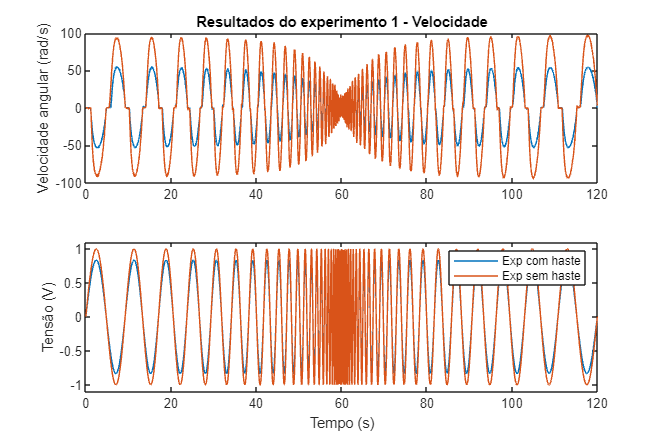

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.omega_1/0.6, exp_2.t, exp_2.omega_1/0.5)
xlim([0 T*2]), ylim([-100 100])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_1.t, exp_1.u/0.6, exp_2.t, exp_2.u/0.5)
xlim([0 T*2]), ylim([-1.1 1.1]), xlabel("Tempo (s)"), ylabel("Tensão (V)")
legend("Exp com haste", "Exp sem haste")

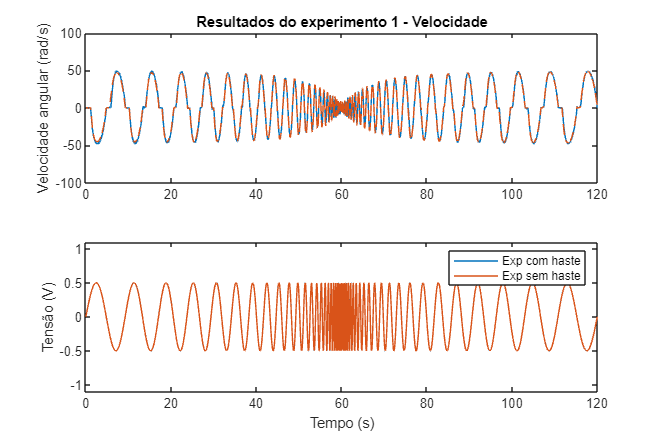

figure("Position", size_image)
subplot(2,1,1)
plot(exp_1.t, exp_1.omega_1*1.5, exp_2.t, exp_2.omega_1, "--")
xlim([0 T*2]), ylim([-100 100])
title("Resultados do experimento 1 - Velocidade"), ylabel("Velocidade angular (rad/s)")

subplot(2,1,2)
plot(exp_1.t, exp_1.u, exp_2.t, exp_2.u)
xlim([0 T*2]), ylim([-1.1 1.1]), xlabel("Tempo (s)"), ylabel("Tensão (V)")
legend("Exp com haste", "Exp sem haste")